**Physics 434: Application of Computers to Physical Measurement **

**11.21.19 **

**Author: Avi Soval **

**Collaborators: Jeff Jiang, Thomas Conaway **

#### **Lab 7: Event Selection Optimization for LHC Data **

**We continue our exploration of the LHC data with a strong QCD background. With our dedicated training sets of confirmed Higgs jets, we want to 'cut' or trim the background QCD data such that the signal-to-noise ratio for this background is maximized. **

h5disp("higgs_100000_pt_250_500.h5"); 

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('qcd_100000_pt_250_500.h5'); 

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000



higgs = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500'); 
qcd = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500'); 

higgs = array2table(higgs,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 
qcd = array2table(qcd,'RowNames',{'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}); 

VariableNames = ["Transverse Momentum (GeV)";"Pseudorapidity";"Azimuthal Angle (rad)";"Invariant Mass";"2-Point ECF Ratio";"3-Point ECF Ratio";"3 to 2 Point ECF Ratio";"Angularity";"t1";"t2";"t3";"t21";"t32";"KtDeltaR"]; 

**First, we plot histograms of the Higgs and QCD invariant mass data, properly normalized to 1. **

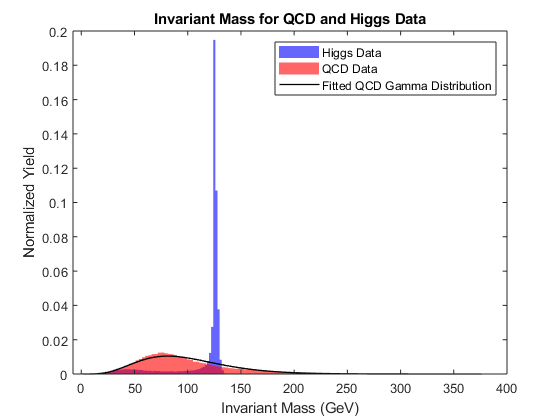

figure(1)
h1 = histogram(higgs{4,:},"EdgeColor",'none',"Normalization",'pdf','FaceColor','blue'); 
hold on 
h2 = histogram(qcd{4,:},"EdgeColor",'none',"Normalization",'pdf','FaceColor','red'); 
hold on 
background = fitdist(qcd{4,:}.','Gamma'); 
x = 0:375; 
plot(pdf(background,x),'LineWidth',1,'Color','black'); 
xlabel('Invariant Mass (GeV)'); 
ylabel('Normalized Yield'); 
title('Invariant Mass for QCD and Higgs Data');
legend('Higgs Data','QCD Data','Fitted QCD Gamma Distribution');  

**By fitting a Gamma distribution to the QCD background, we can calculate the significance of the 125 GeV Higgs detection. **

prob = cdf(background,125,'upper'); 
sigma = norminv(prob); 
disp("The 125 GeV Higgs spike has a sigma of " + abs(sigma))

The 125 GeV Higgs spike has a sigma of 0.74368


**With such a low significance for the 125 GeV spike, it would be improper to assume this detection has not been caused by a background fluctuation. Additionally, this significance is somewhat misleading since the datasets for the Higgs and QCD have not been properly normalized based off their expected yields. Thus, we must re-normalize each histogram by their respective expected yields,**$N_{Higgs}$ **= 100 and **$N_{QCD}
$ **= 20,000. We should then be able to compare the properly normalized area under each histogram and find an appropriate signal-to-noise ratio, the optimization of which is the primary goal of this lab. We complete this process for all 14 independent variables, and plot the stacked histograms of Higgs signal and QCD background data below.  **

higgs_expected_yield = randi([1 100000],1,100); 
qcd_expected_yield = randi([1 100000],1,20000); 

higgs_test = higgs{:,higgs_expected_yield}; 
qcd_test = qcd{:,qcd_expected_yield}; 

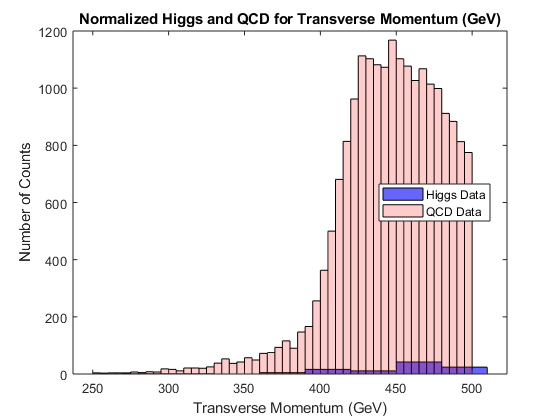

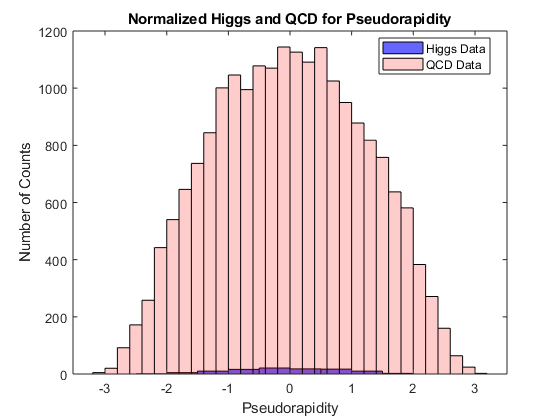

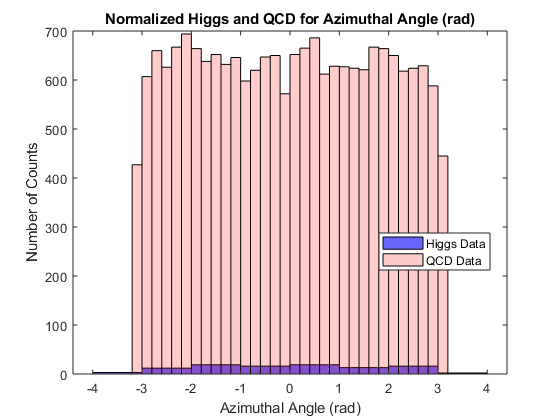

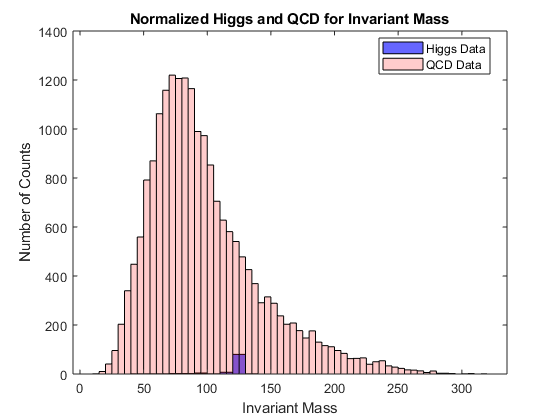

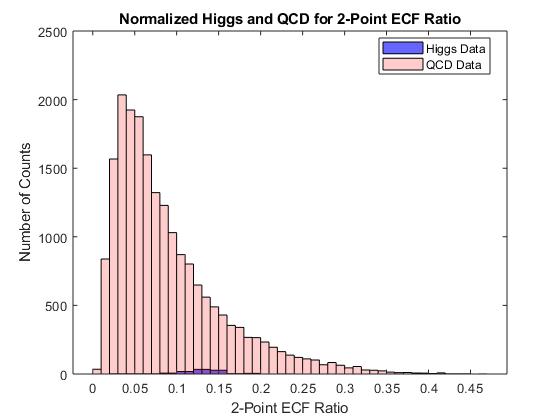

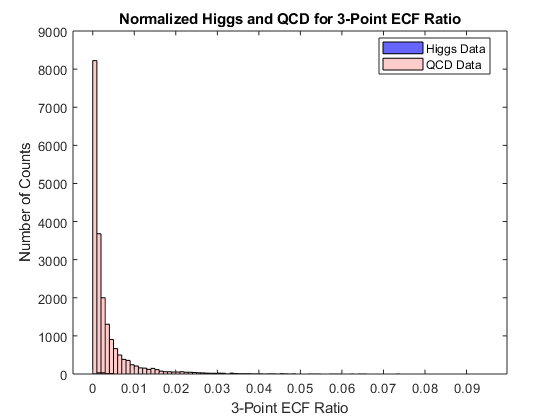

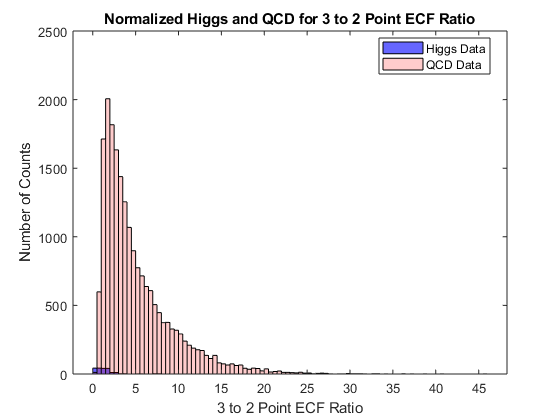

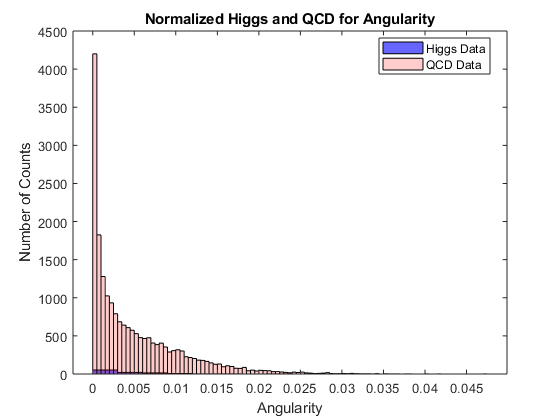

for i = 1:14
    
    figure(i+1)
    histogram(higgs_test(i,:),'FaceColor','blue'); 
    hold on 
    histogram(qcd_test(i,:),'FaceColor','red','FaceAlpha',0.2); 
    xlabel(VariableNames(i)); 
    ylabel('Number of Counts'); 
    title("Normalized Higgs and QCD for " + VariableNames(i)); 
    legend('Higgs Data','QCD Data','Location','best');     
    
end


% higgs_edges = h1.BinEdges; 
% higgs_counts = h1.BinCounts/sum(h1.BinCounts) * 100; 
% 
% qcd_edges = h2.BinEdges; 
% qcd_counts = h2.BinCounts/sum(h2.BinCounts) * 20000; 
% 
% figure(2)
% histogram('BinEdges',higgs_edges,'BinCounts',higgs_counts,'FaceColor','black'); 
% hold on
% histogram('BinEdges',qcd_edges,'BinCounts',qcd_counts,'FaceColor','blue','FaceAlpha',0.1);
% xlabel('Invariant Mass (GeV)'); 
% ylabel('Normalized to Expected Yield'); 
% title('Invariant Mass for Higgs and QCD, Normalized to Expected Yield'); 
% legend('Higgs, Yield = 100','QCD, Yield = 20000'); 

**Since the expected yield for the QCD background is 200 times the size of the Higgs signal, the stacked histograms above show the background data completely overshadowing the signal. This means that our ratio of N_Higgs/sqrt(N_QCD) will always be significantly less than 1. As we make different cuts to the data, this ratio will increase towards an optimum value (for each variable), though it will still remain less than 1 due to the comparative sizes of the expected yields. **

**Now, we can begin making cuts to the data. The goal of this is to omit as much QCD background while preserving as much Higgs signal as possible. As a result, our ideal discriminator variables would be ones where the Higgs histogram is neatly clustered (not spread out) in a small range compared to the spread of the QCD. This would allow us to make cuts that would remove large amounts of background data while minimizing the signal removed. We seek to find the optimal set of cuts for *****each *****variable that maximizes this signal to noise ratio. **

% creating data set for each variable 

rowNames = {'pt';'eta';'phi';'mass';'ee2';'ee3';'d2';'angularity';'t1';'t2';'t3';'t21';'t32';'KtDeltaR'}; 

**In the following section, we produce sets of cuts for each variable. In each case, we define a lower and upper threshold. All Higgs and QCD data points that fall within this range - i.e above the lower threshold and below the upper threshold - are preserved while all data points outside this range are omitted. We then calculate the signal to noise ratio, interpreted as **$\frac{N_{\mathrm{Higgs}} }{N_{\mathrm{QCD}} }$**, from the size of the final preserved Higgs and QCD datasets. Since we are looking for an optimal signal to noise ratio depending on the location of our cuts (or thresholds), we iterate over a large set of possible ranges. Specfically, we split the total range of the dataset into a linearly spaced coordinate vector of 50 values. We then define a pair of lower and upper thresholds from this dataset that can be any combination of the vector values, provided that the upper threshold is greater than the lower threshold. Analyzing every combination of thresholds that satisfies this criteria yields 1250 (2500 / 2) possible ranges for each variable that we can simulate the signal to noise ratio for. Afterwards, the optimal signal to noise ratio for each set and its corresponding threshold range are recorded. **

**Below are the 14 2-D surface plots displaying the SNR of each variable, for all possible combinations of ranges. The triangular nature of these plots is due to the earlier constraint that we established, which required that the upper threshold value be greater than the lower. In each plot, a red dot has been placed at the grid location corresponding to the maximum SNR ratio. For example, a dot at the location (x,y) = (upper threshold, lower threshold) means that the optimal signal to noise ratio is found by looking only at the data below x (upper threshold) and above y (lower threshold), and cutting anything outside this range.**

**In some cases on the outer edges of each variable's distribution (see the histograms), the total number of Higgs and QCD data points sharply drops off. As a result, the SNR in these ranges can be significantly high (a preserved Higgs set of 20 datapoints and a preserved QCD set of 100 could theoretically produce an SNR of 0.2, despite this having omitted nearly all the data from both sets). To ensure that the ideal ranges remained within the body of the distribution and avoided the periphery, we implemented an additional constraint that required the total number of preserved data points to exceed 5000. Essentially, we wanted to make sure that we were still looking at an appreciable amount of data when trying to find the optimum signal to noise ratio. I have not yet explored how changing this filter impacts the precision of our final ranges - by increasing or decreasing the minimum required number of total data points, we can either allow our ideal range to fall outside most of the data, or force it to expand enough that it contains the necessary number of points. This is then a spectrum that has highly precise but misleading ranges on one end and large but low-accuracy ranges on the other. Ideally, there should be some optimum minimum requirement for the final dataset size that balances both sides of this spectrum. **

**A table for convenience has also been displayed below. It contains the optimum signal to noise ratio as well as its corresponding range (lower and upper thresholds) for all 14 variables. **

ratio_variableNames = {'Tested_Variable','Optimum_SNR','Lower_Threshold','Upper_Threshold'}; 
ratio_variableTypes = {'string','double','double','double'}; 
optimum_ratio = table('Size',[14 4],'VariableTypes',ratio_variableTypes,'VariableNames',ratio_variableNames); 
all_ratios = zeros(50,50,14); 

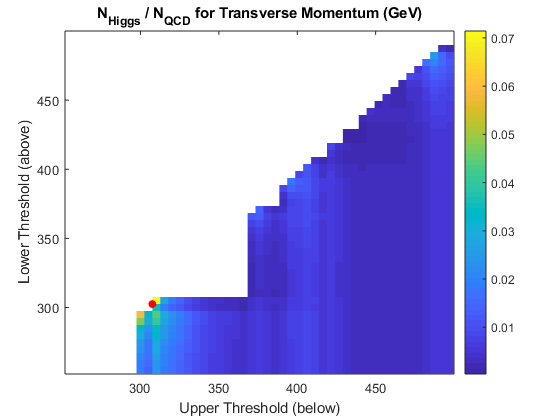

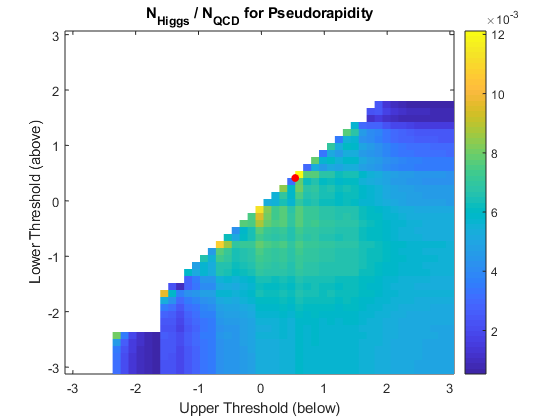

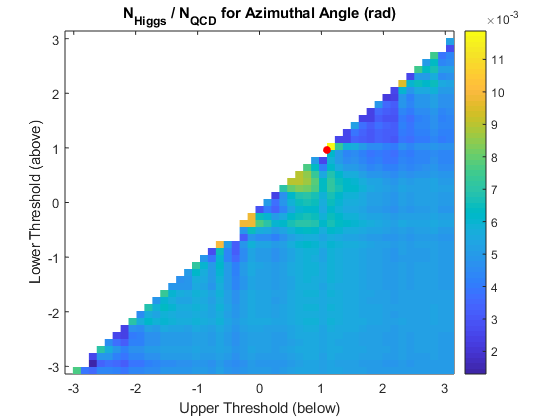

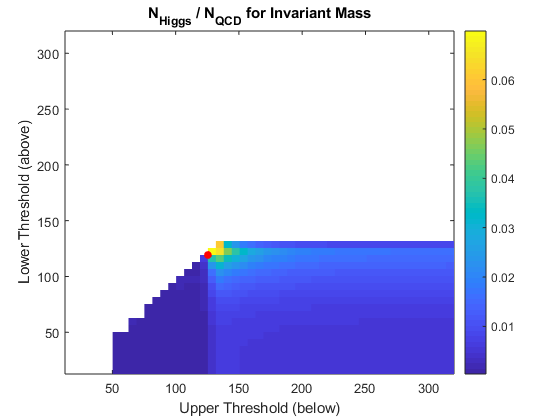

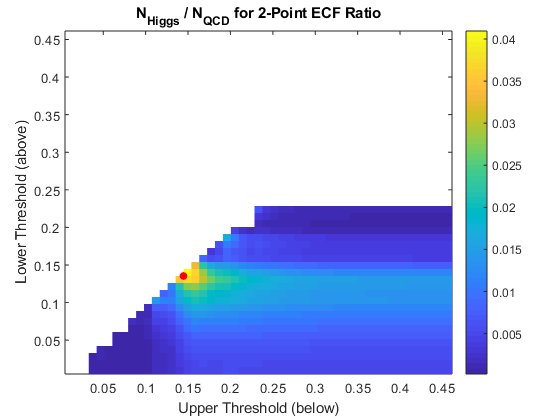

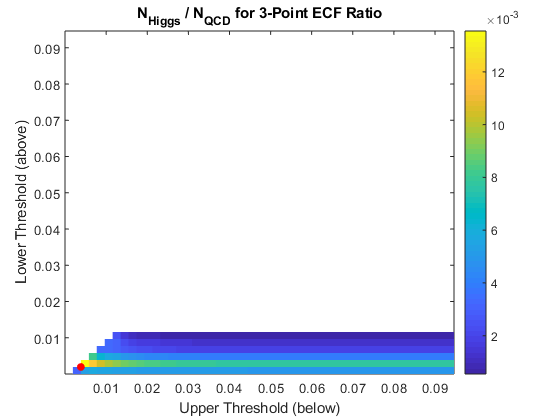

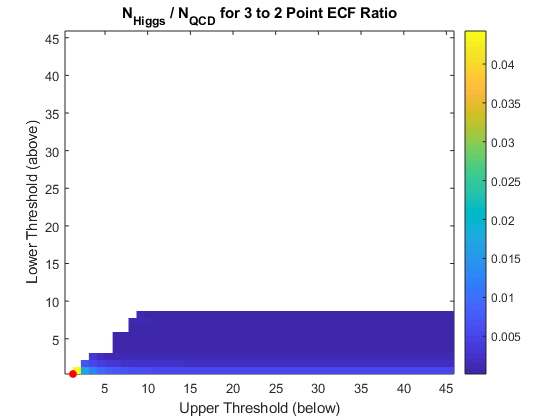

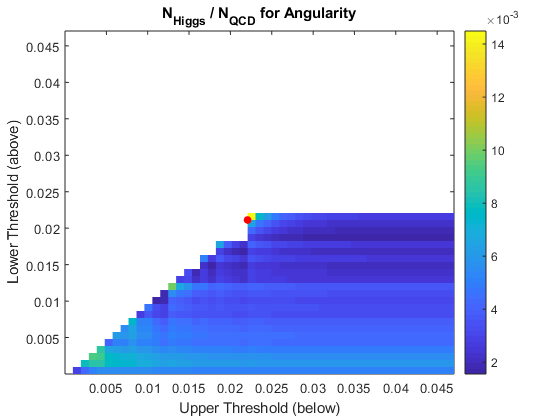

for k = 1:14
    
mins = [min(higgs_test(k,:)) min(qcd_test(k,:))]; 
maxs = [max(higgs_test(k,:)) max(qcd_test(k,:))]; 
 
steps = linspace(min(mins),max(maxs),50); 

higgs_cut = higgs_test(k,:); 
qcd_cut = qcd_test(k,:); 

[bounds,scratch] = meshgrid(steps,steps); 

for i = 1:length(steps)
    
    for j = 1:length(steps)
        
        if steps(j) <= steps(i)
            all_ratios(i,j,k) = NaN; 
            continue
        end
        
        higgs_pass = higgs_cut(higgs_cut > steps(i) & higgs_cut <= steps(j)); 
        qcd_pass = qcd_cut(qcd_cut > steps(i) & qcd_cut <= steps(j)); 
        
        if length(higgs_pass) + length(qcd_pass) < 5000
            
            all_ratios(i,j,k) = NaN; 
            
        end
        
        if isempty(qcd_pass) == 1
            
            all_ratios(i,j,k) = NaN; 
            
        else
            
            all_ratios(i,j,k) = length(higgs_pass)/length(qcd_pass); 
            
        end
    end
end

current_ratio = all_ratios(:,:,k); 
current_ratio(current_ratio==0) = NaN; 
all_ratios(:,:,k) = current_ratio; 

[max_ratio,index] = max(current_ratio(:)); 
[bestrow,bestcol] = ind2sub(size(current_ratio),index); 
% [maxes,indices] = sort(testratios(isnan(testratios(:))==0),'descend'); 
% [maxrow,maxcol] = ind2sub(size(testratios),indices(1:10)); 

figure(15+k)
h = pcolor(steps,steps,all_ratios(:,:,k));  
hold on 
plot(steps(bestcol),steps(bestrow),'.r','markersize',20); 
colorbar
h.EdgeColor = 'none'; 
xlabel('Upper Threshold (below)'); 
ylabel('Lower Threshold (above)'); 
title("{N_{Higgs} / N_{QCD}} for " + VariableNames(k)); 

optimum_ratio{k,1} = VariableNames(k); 
optimum_ratio{k,2} = max_ratio;
optimum_ratio{k,3} = steps(bestrow); 
optimum_ratio{k,4} = steps(bestcol); 

end


disp(optimum_ratio)

          Tested_Variable          Optimum_SNR    Lower_Threshold    Upper_Threshold
    ___________________________    ___________    _______________    _______________

    "Transverse Momentum (GeV)"     0.071429            302.51             307.57   
    "Pseudorapidity"                0.012113            0.4123            0.53862   
    "Azimuthal Angle (rad)"         0.011876           0.96145             1.0896   
    "Invariant Mass"                0.069837            119.23             125.51   
    "2-Point ECF Ratio"             0.040948           0.13534            0.14465   
    "3-Point ECF Ratio"              0.01355         0.0019328          0.0038636   
    "3 to 2 Point ECF Ratio"        0.044235            0.3152             1.2453   
    "Angularity"                    0.014493          0.021121           0.022081   
    "t1"     